% Tensor Component Analysis (TCA): 
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
condition = ['BLA'];
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

data = EEG.data(:, :, epoch_trials);

% Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(data)); % Preallocate
for epoch = 1:size(data, 3)
    beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)'; % ch x time x trial
end

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 1020ms)
% 512 sample/sec x 0.4 sec = 204.8
% Load trial numbers from Excel file


% Define pre-stimulus window (same for both conditions)
pre_window = [-0.4, 0];
post_window = [0, 0.4];

% % Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

% TCA on pre-stimulus window
pre_data = beta_signal(:, pre_idx,:); % ch x time x trial

%[U_pre,output_pre] = cpd(pre_data, 60);

% TCA on post-stimulus window
post_data = beta_signal(:, post_idx,:); % ch x time x trial

%[U_post,output_post] = cpd(post_data, 60);

% Define the range of components to test
num_components = 1:50;  % Test 1 to 50 components
reconstruction_errors_pre = zeros(size(num_components));
explained_variance_pre = zeros(size(num_components));
reconstruction_errors_post = zeros(size(num_components));
explained_variance_post = zeros(size(num_components));

if isempty(gcp('nocreate'))
    parpool; % Uses default number of workers
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).




parfor idx = 1:length(num_components)
    k = num_components(idx);

    [U_pre, ~] = cpd(pre_data, k, 'Display', 0);
    reconstructed_pre = cpdgen(U_pre);
    error_pre = norm(pre_data(:) - reconstructed_pre(:)) / norm(pre_data(:));
    reconstruction_errors_pre(idx) = error_pre;
    explained_variance_pre(idx) = 1 - error_pre^2;

    [U_post, ~] = cpd(post_data, k, 'Display', 0);
    reconstructed_post = cpdgen(U_post);
    error_post = norm(post_data(:) - reconstructed_post(:)) / norm(post_data(:));
    reconstruction_errors_post(idx) = error_post;
    explained_variance_post(idx) = 1 - error_post^2;
end

> In cpd_core/state (line 205)
In cpd_core/grad (line 270)
In 

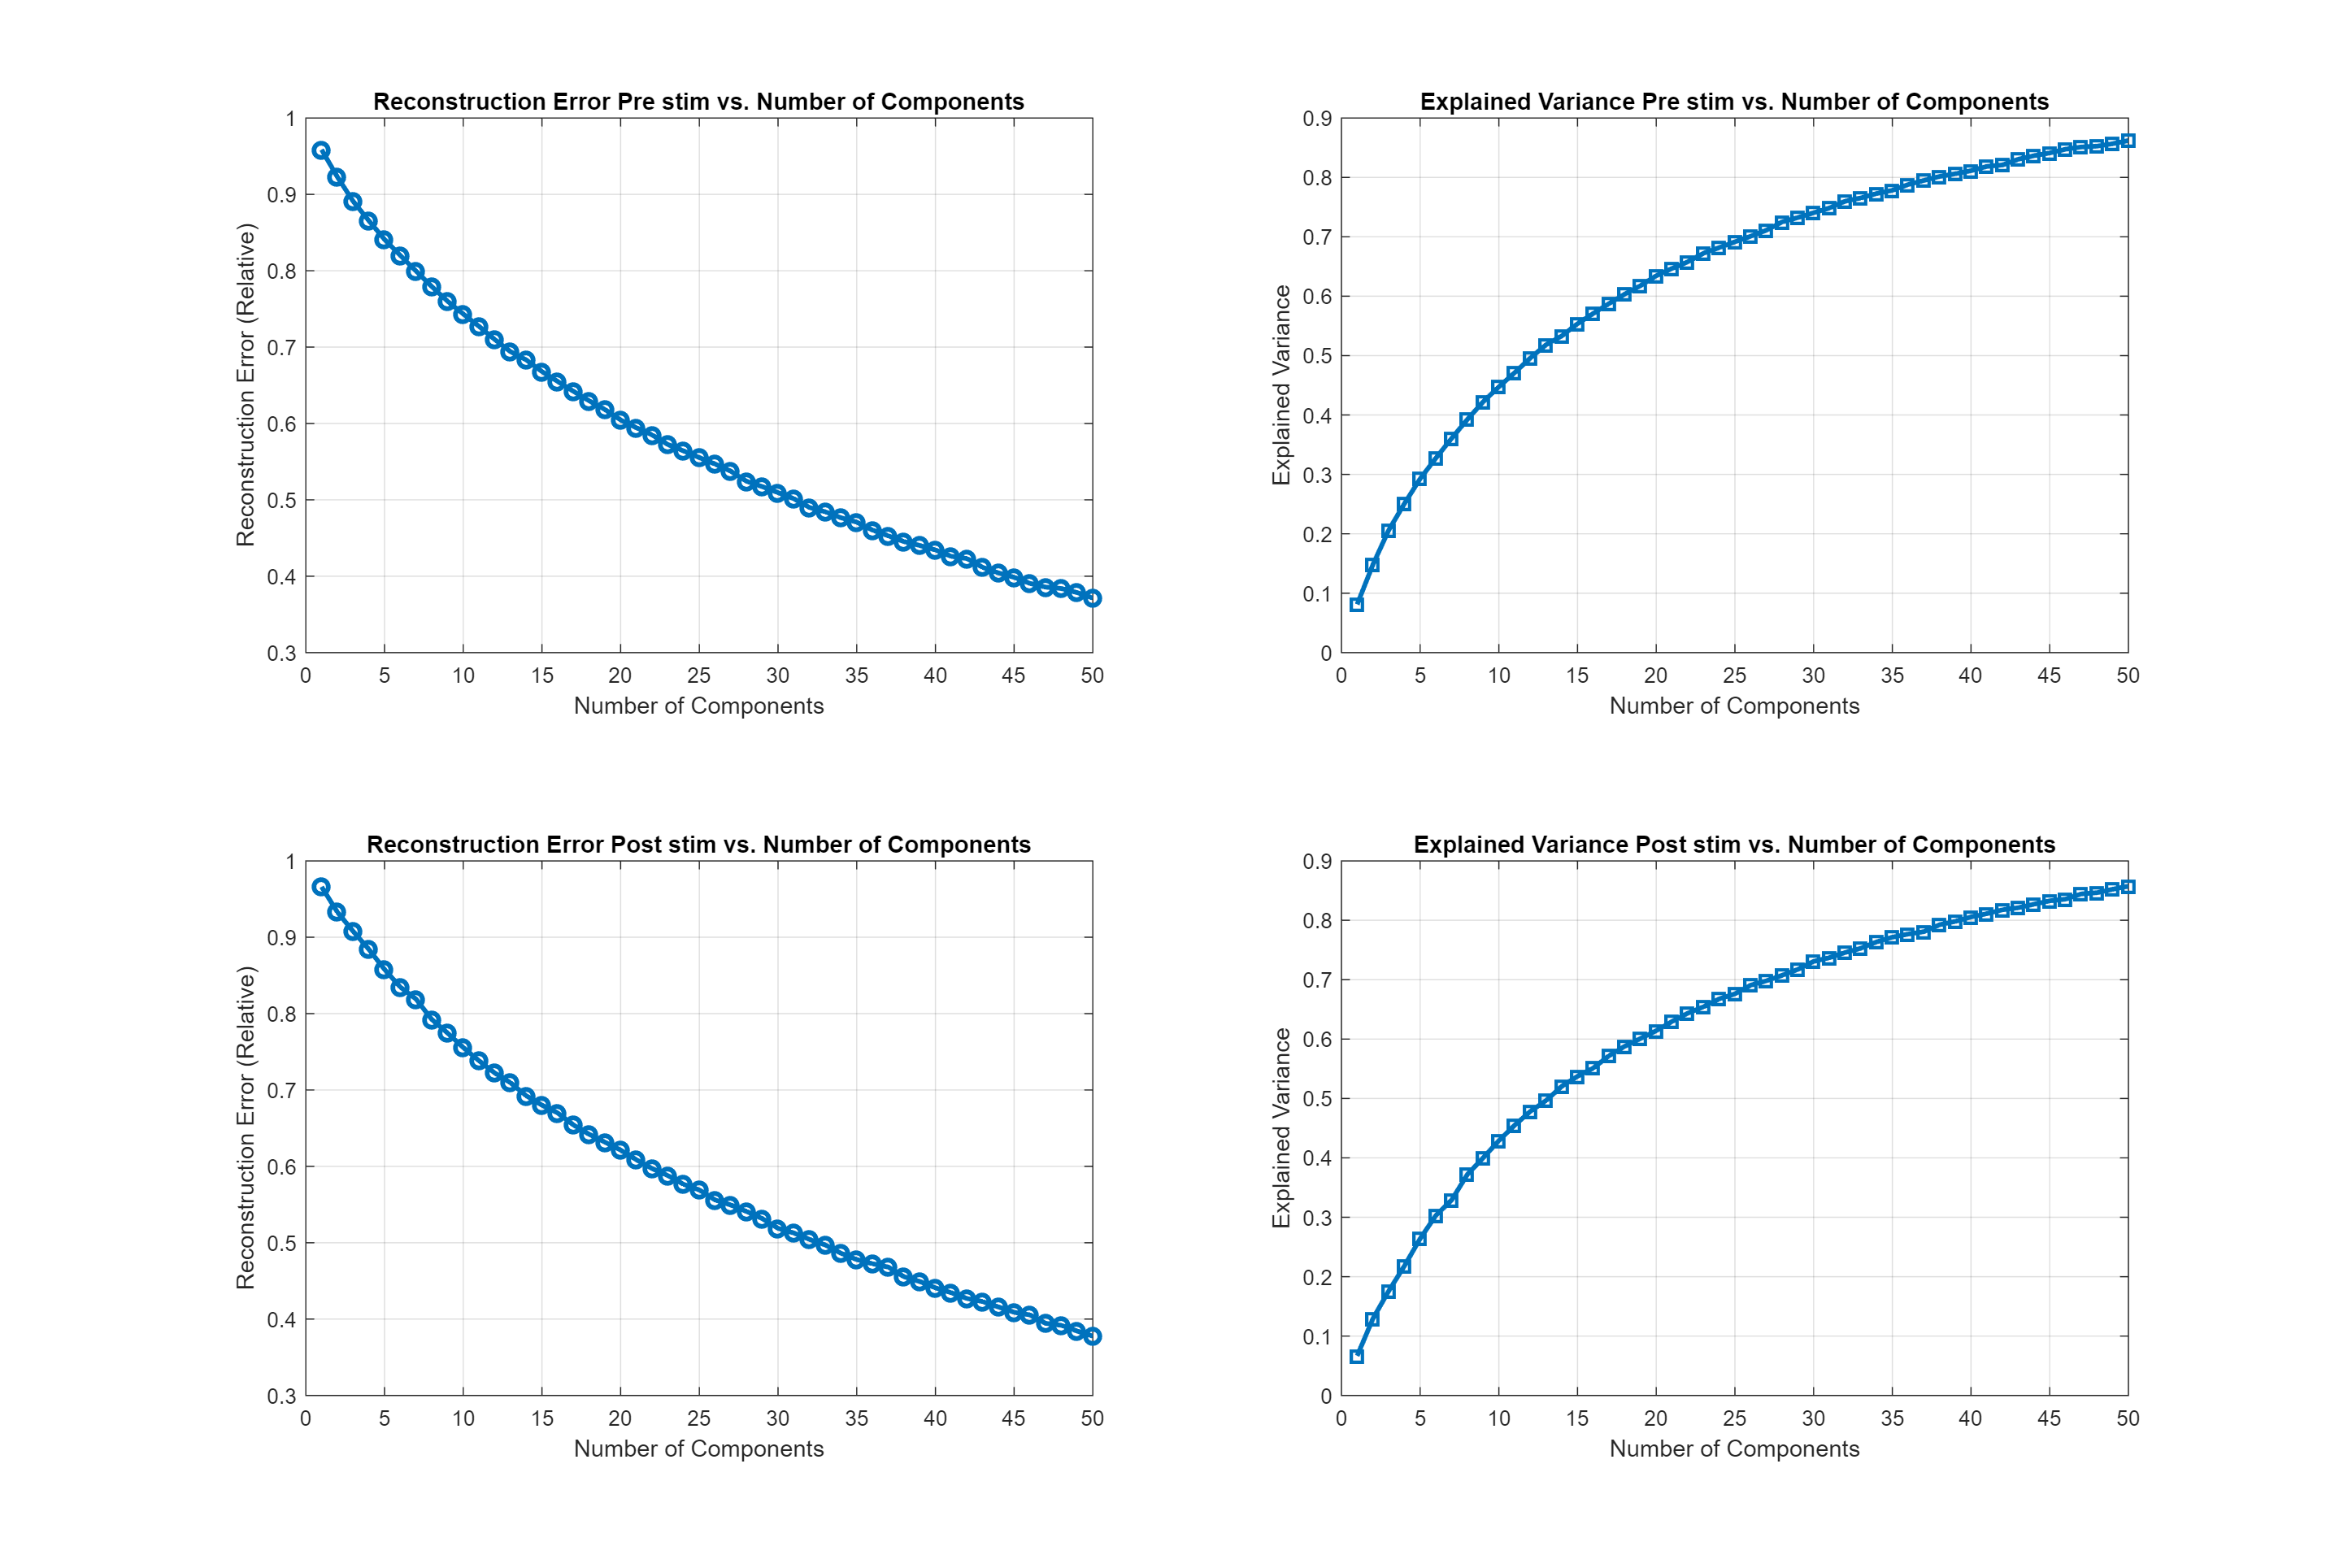

% Plot reconstruction error
figure('Position', [100, 100, 1500, 1000]); % [x, y, width, height]
subplot(2,2,1)
plot(num_components, reconstruction_errors_pre, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Pre stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,2)
plot(num_components, explained_variance_pre, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Pre stim vs. Number of Components');
grid on;

subplot(2,2,3)
plot(num_components, reconstruction_errors_post, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error Post stim vs. Number of Components');
grid on;

% Plot explained variance
subplot(2,2,4)
plot(num_components, explained_variance_post, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance Post stim vs. Number of Components');
grid on;

threshold = 0.85;  % Target explained variance threshold

% Preallocate result
pc_at_85_pre = zeros(1, 1);
pc_at_85_post = zeros(1, 1);

for i = 1:size(explained_variance_pre, 2)
    idx_pre = find(round(explained_variance_pre(i),2) >= threshold, 1, 'first');     % Find first PC where cumulative sum ≥ 85
    idx_post = find(round(explained_variance_post(i),2) >= threshold, 1, 'first'); 

    if ~isempty(idx_pre)
        pc_at_85_pre = idx_pre ;
    elseif ~isempty(idx_post)
        pc_at_85_post = idx_post ; 
%     else
%         pc_at_85_pre = NaN;
%         pc_at_85_post = NaN;
    end
end


% Chosing to do TCA on the first 46 components since they explain 85% of
% the variance
[U_pre,output_pre ] = cpd(pre_data, 46);
num_components = size(U_pre{1}, 2); % Number of components
t = tiledlayout(num_components,3);

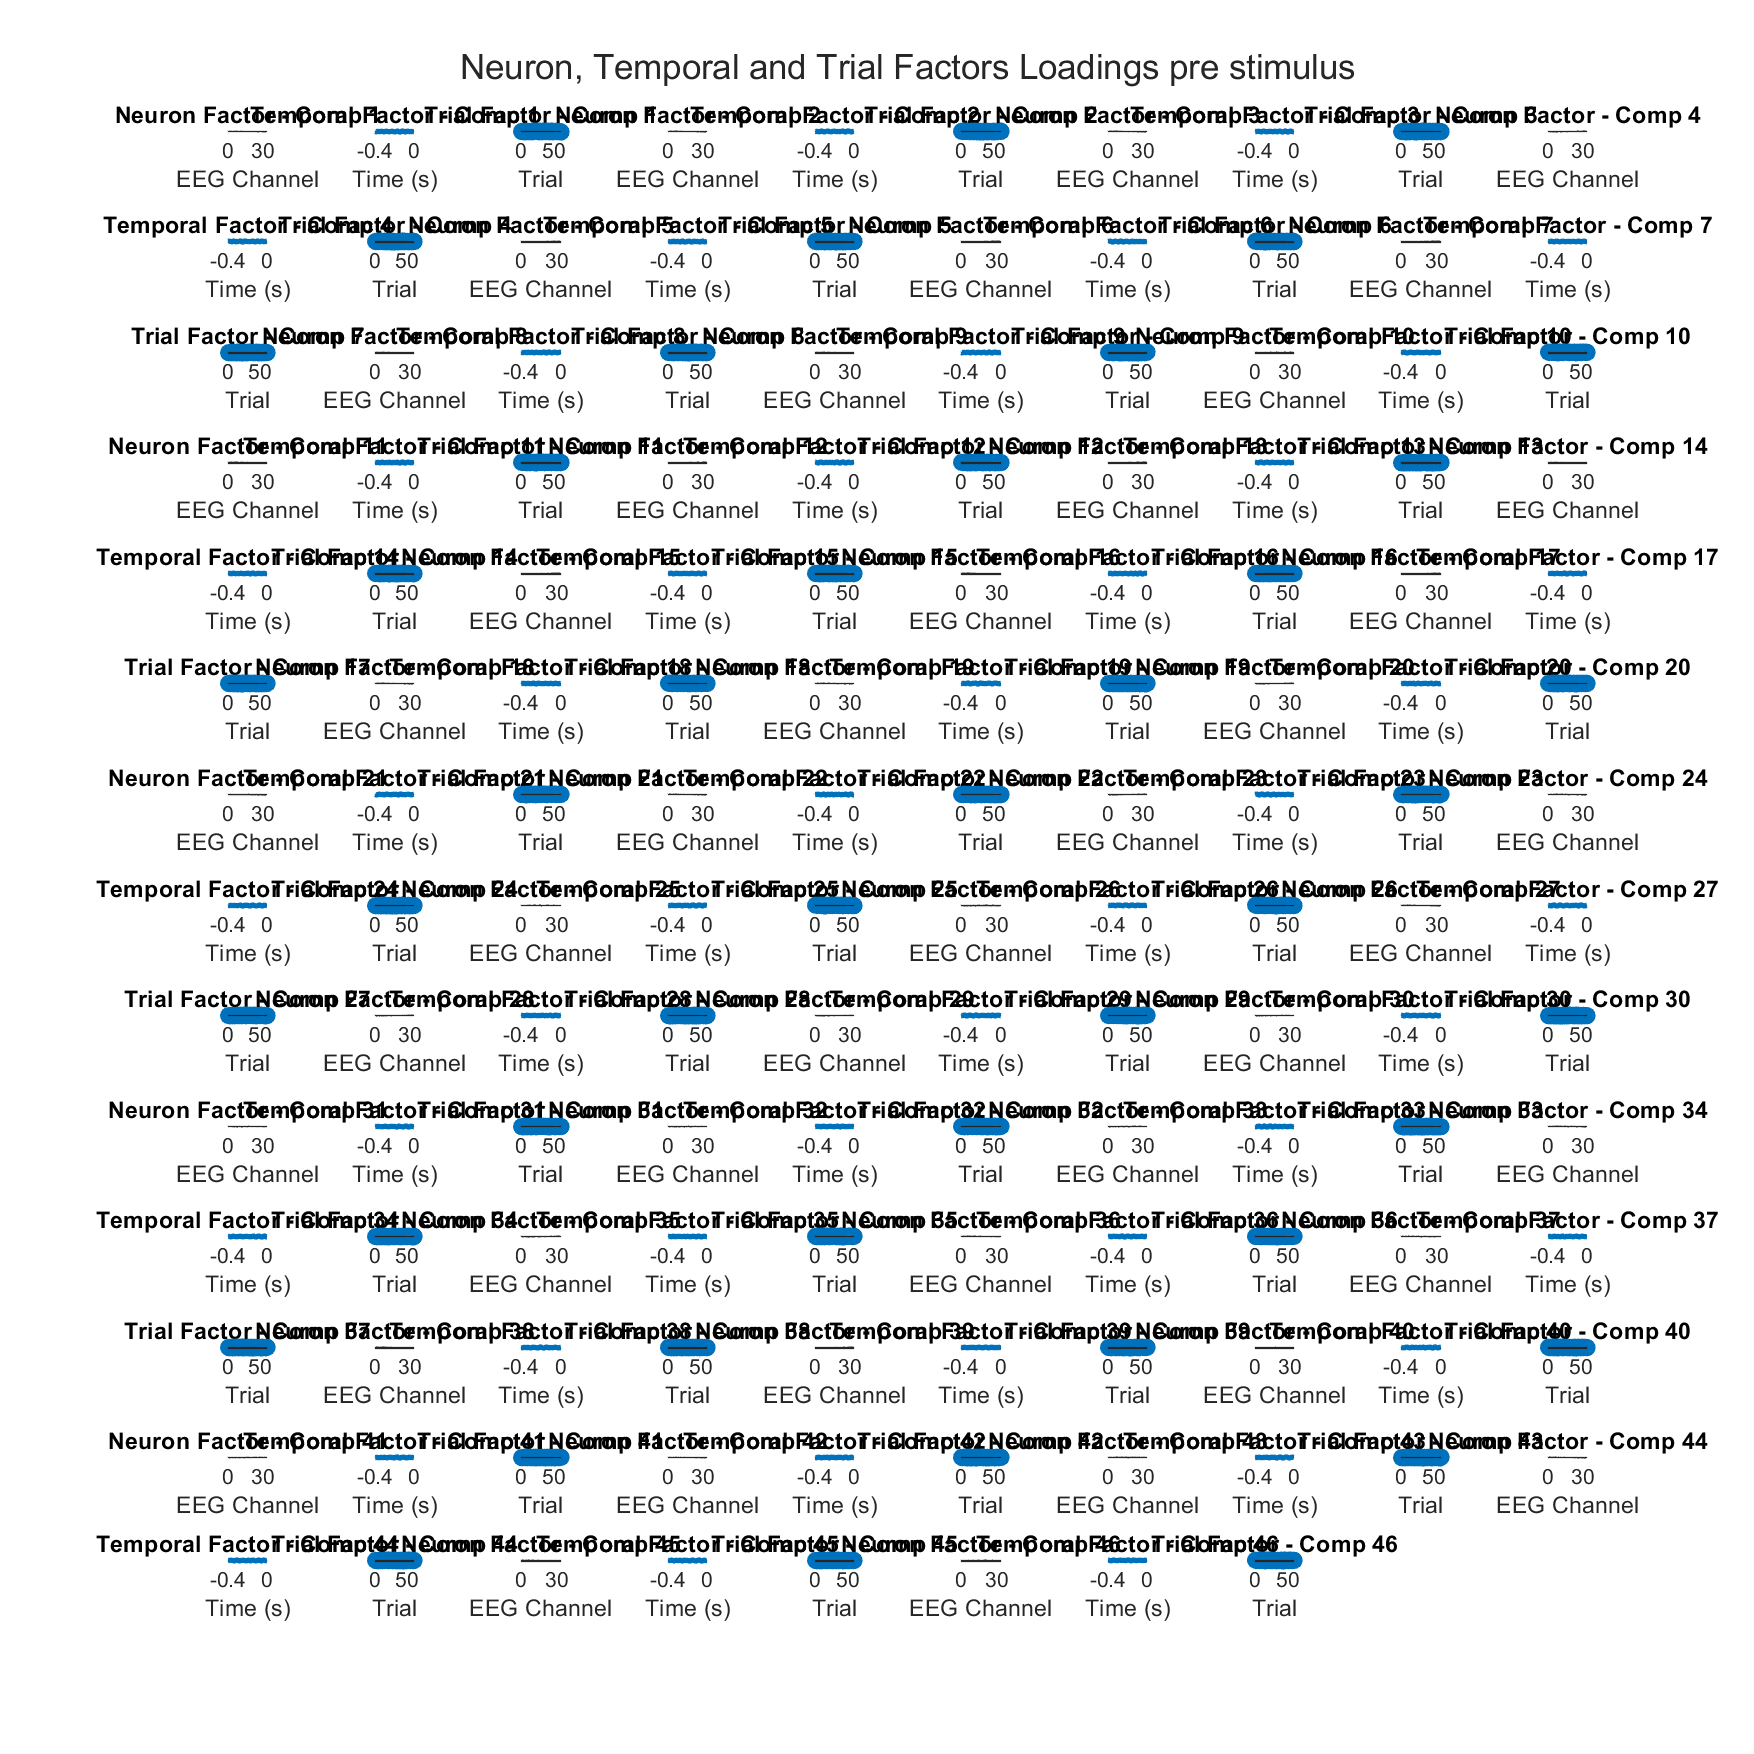

figure('Position', [100, 100, 1200, 1200]); % [x, y, width, height]

for comp = 1:num_components
    nexttile;
    bar(U_pre{1}(:, comp)); % Bar plot for each component
    title(['Neuron Factor - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    nexttile;
    plot(time_vector(pre_idx), U_pre{2}(:, comp), 'LineWidth', 2);
    title(['Temporal Factor - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    nexttile;
    stem(U_pre{3}(:, comp), 'filled');
    title(['Trial Factor - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end
sgtitle('Neuron, Temporal and Trial Factors Loadings pre stimulus');


% % Temporal Factor (Time Loadings)
% figure;
% for comp = 1:num_components
%     subplot(ceil(num_components / 8), 8, comp);
%     plot(time_vector(pre_idx), U_pre{2}(:, comp), 'LineWidth', 2);
%     title(['Temporal Factor - Comp ' num2str(comp)]);
%     xlabel('Time (s)');
%     ylabel('Loading');
%     grid on;
% end
% sgtitle('Temporal Factor Time Courses pre stimulus');
% 
% % Trial Factor (Trial Contributions)
% figure;
% for comp = 1:num_components
%     subplot(ceil(num_components / 8), 8, comp);
%     stem(U_pre{3}(:, comp), 'filled');
%     title(['Trial Factor - Comp ' num2str(comp)]);
%     xlabel('Trial');
%     ylabel('Loading');
%     grid on;
% end
% sgtitle('Trial Factor Contributions pre stimulus');


% Chosing to do TCA on the first 48 components since they explain 85% of
% the variance for post stimulus
[U_post,output_post ] = cpd(post_data, 48);
num_components = size(U_post{1}, 2); % Number of components

figure('Position', [100, 100, 1200, 1200]); % [x, y, width, height]

for comp = 1:num_components
    nexttile;
    bar(U_post{1}(:, comp)); % Bar plot for each component
    title(['Neuron Factor - Comp ' num2str(comp)]);
    xlabel('EEG Channel');
    ylabel('Loading');
    grid on;

    nexttile;
    plot(time_vector(post_idx), U_post{2}(:, comp), 'LineWidth', 2);
    title(['Temporal Factor - Comp ' num2str(comp)]);
    xlabel('Time (s)');
    ylabel('Loading');
    grid on;

    nexttile;
    stem(U_post{3}(:, comp), 'filled');
    title(['Trial Factor - Comp ' num2str(comp)]);
    xlabel('Trial');
    ylabel('Loading');
    grid on;
end
sgtitle('Neuron, Temporal and Trial Factors Loadings post stimulus');
% Neuron Factor (EEG channels)
% figure;
% for comp = 1:num_components
%     subplot(ceil(num_components / 8), 8, comp); % Adjust for 4 columns
%     bar(U_post{1}(:, comp)); % Bar plot for each component
%     title(['Neuron Factor - Comp ' num2str(comp)]);
%     xlabel('EEG Channel');
%     ylabel('Loading');
%     grid on;
% end
% sgtitle('Neuron Factor Loadings post stimulus');
% 
% % Temporal Factor (Time Loadings)
% figure;
% for comp = 1:num_components
%     subplot(ceil(num_components / 8), 8, comp);
%     plot(time_vector(post_idx), U_post{2}(:, comp), 'LineWidth', 2);
%     title(['Temporal Factor - Comp ' num2str(comp)]);
%     xlabel('Time (s)');
%     ylabel('Loading');
%     grid on;
% end
% sgtitle('Temporal Factor Time Courses post stimulus');
% 
% % Trial Factor (Trial Contributions)
% figure;
% for comp = 1:num_components
%     subplot(ceil(num_components / 8), 8, comp);
%     stem(U_post{3}(:, comp), 'filled');
%     title(['Trial Factor - Comp ' num2str(comp)]);
%     xlabel('Trial');
%     ylabel('Loading');
%     grid on;
% end
% sgtitle('Trial Factor Contributions post stimulus');